%% AUTHOR INFORMATION
% NAME: Balaji V
% EMAIL: ee19d2020@smail.iitm.ac.in
% Code to analyse the output from ./Test_Write_Drivers

## Preface

    clear ;
    clc ;
    if( ~exist( 'globalVars', 'var' ) )
        globalVars=[];
    end
    eval( [ 'clearvars -except globalVars ' sprintf( '%s ', globalVars ) ] ) ;
    close all ;
    zeroes = @( x ) zeros( x ) ;
    addpath("D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\lowerLevelCode\FPGA_COMMUNICATE");
    addpath("D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\lowerLevelCode\FPGA_CONTROL");
    addpath("D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\lowerLevelCode\MISC");
    addpath("D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\lowerLevelCode\POWER_SUPPLY_CONTROL");


## Go to Global

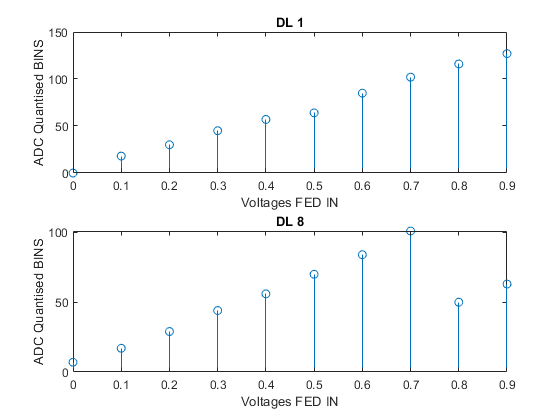

% Global : D:\Xilinx\Vivado_2018_Projs\Srinidhi_Laptop\PCB_TEST_FPGA_ARM\Character_Files\new_C_code_UART_files\10_vecfile_auto_FA\7_vecfile_auto_FA
% cd( '../../../' ) ;
%     fileName = mfilename ; 
    filePath = matlab.desktop.editor.getActiveFilename ;
    b = find( filePath == '\', 1, 'last' ) ; 
    fileName = filePath( ( b + 1 )  : ( end - 4 ) ) ;
    b = find( fileName == '_', 1, 'last' ) ; 
    sourceFileName = 'voltageInHybridADC' ;
driverCode_fileName         = sprintf( '/%s', sourceFileName ) ;
filePath            = '.' ;
fpgaReceivedFile_name       = [ filePath '/fpgaRcvdFiles' driverCode_fileName ] ;
[    fpgaReceivedFile_decrypted ...
            , adc_VPVN ...
            , adc_AUX00 ...
            ,    SA_SC_collect    ...
            ,    ADC_SC_collect  ...
            ,    AdderTree_SC_collect  ...
            ,    SARTIMING_OUT_SC_collect  ...
            ,    WRITE_2_SC_collect  ...
            ,    WRITE_1_SC_collect  ...
            ,    WRITE_0_SC_collect  ...
            ,    IMC_RBL_SC_collect  ...
            ,    IMC_VOut_SC_collect  ...
            ,    WWL_SC_collect  ...
            ,    FLOATADC_SC_collect  ...
            ,    SARTIMING_IN_SC_collect  ...
            ,    ControlPath_SC_collect  ...
            ,    Reset_DFF_collect  ...
            ,    SAR_Bin_Num ...
            ,     read_SRAM_collect_Cell...
            ,    perform_hybridIMC_BLIMG_FPGA_collect...
            ,    perform_internalIMC_ImgBankFPGA_collect  ] = decrypt_and_RSC( fpgaReceivedFile_name ) ;
%% cd'ing back
    cd( filePath ) ;
%% saving data
    c = clock ;
    year    = c(1) ;
    month   = c(2) ; 
    day     = c(3) ;
    hour    = c(4) ;
    minute  = c(5) ;
    seconds = floor(c(6)) ;
save( [ sprintf( './analyzeResults/%s_%s_%d_%d_%d', fileName, date,hour,minute,seconds) ] ) ;

ADC_predicted=[];
ADC_predicted_bits=[];
for iter=1:size(perform_hybridIMC_BLIMG_FPGA_collect,1)
    a=reshape(perform_hybridIMC_BLIMG_FPGA_collect(iter,:),[],92);b=2.^[0,1,2,3,4,5,6]';c=b'*a;ADC_predicted=[ADC_predicted;c];d=a';d=reshape(d,1,92,7);ADC_predicted_bits=[ADC_predicted_bits;d];
end
ADC_predicted_Dec=ADC_predicted;
%save("INL_DNL.mat",INL,DNL);
%save("ADC_predicted_bits.mat","ADC_predicted_bits");
%save("ADC_predicted_Dec.mat","ADC_predicted_Dec");
ADC_predicted_volts=(ADC_predicted/(2^7))*0.9;

ZEDBOARD_ADC=reshape(adc_VPVN,88,[]);ZEDBOARD_ADC=ZEDBOARD_ADC';
ZEDBOARD_ADC_Ref=reshape(adc_AUX00,88,[]);ZEDBOARD_ADC_Ref=ZEDBOARD_ADC_Ref';

numOnesRefArray=[142:-4:105];
numOnesData_DL_array=147;

IMCVOutvolt_arr=[0:0.1:0.9];
xdata=IMCVOutvolt_arr;
DL_indices=[1:18,27:62,71:88];
RL_indices=[19:26,63:70];
DL_ADCs=ADC_predicted_Dec(:,DL_indices+2);
figure(1);

subplot(2,1,1);
stem(xdata,DL_ADCs(:,1));
title('DL 1');
xlabel('Voltages FED IN');
ylabel('ADC Quantised BINS');

subplot(2,1,2);
stem(xdata,DL_ADCs(:,8));
title('DL 8');
xlabel('Voltages FED IN');
ylabel('ADC Quantised BINS');

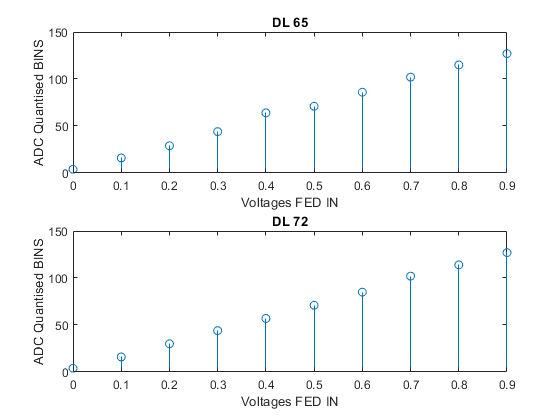


figure(2);
subplot(2,1,1);
stem(xdata,DL_ADCs(:,65));
title('DL 65');
xlabel('Voltages FED IN');
ylabel('ADC Quantised BINS');

subplot(2,1,2);
stem(xdata,DL_ADCs(:,72));
title('DL 72');
xlabel('Voltages FED IN');
ylabel('ADC Quantised BINS');